x = linspace(0,1,20);
t = linspace(0,2,5);
m = 0;
sol = pdepe(m,@pdex1pde,@pdex1ic,@pdex1bc,x,t);
u = sol(:,:,1);

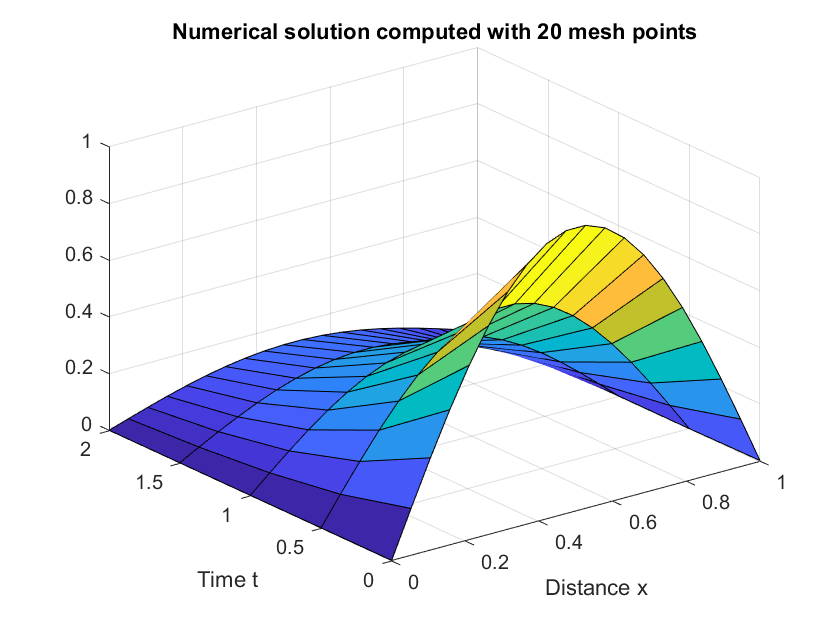


surf(x,t,u)
title('Numerical solution computed with 20 mesh points')
xlabel('Distance x')
ylabel('Time t')

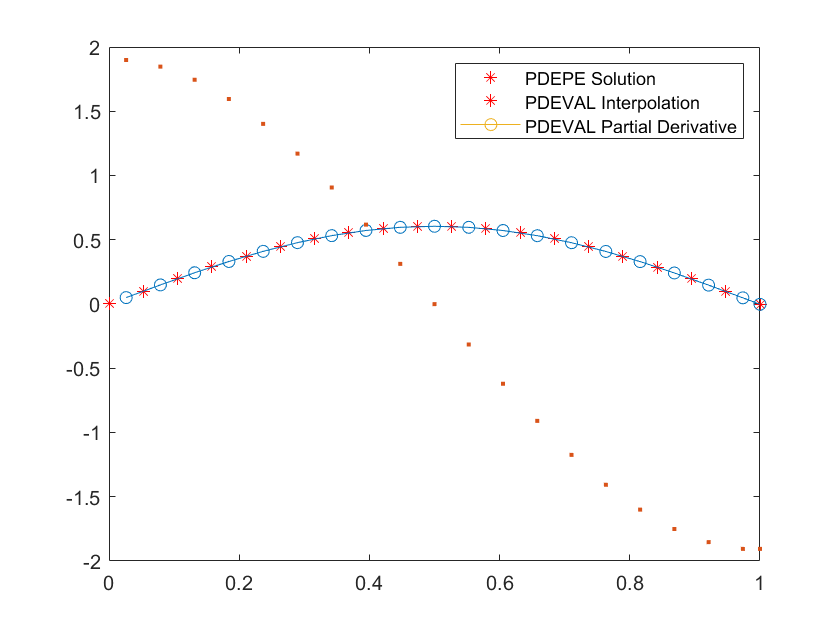

% evaluate space mesh
xq = x;
xq(1:end-1) = xq(1:end-1) + diff(xq)./2;
[uv,dudx] = pdeval(m,x,sol(2,:),xq);
plot(x,sol(2,:),'r*')
hold on
plot(xq,uv,'-o')
plot(xq,dudx,'.')
hold off
legend('PDEPE Solution', 'PDEVAL Interpolation', 'PDEVAL Partial Derivative')

function [c,f,s] = pdex1pde(x,t,u,dudx) % Equation to solve
c = pi^2;
f = dudx;
s = 0;
end
%----------------------------------------------
function u0 = pdex1ic(x) % Initial conditions
u0 = sin(pi*x);
end
%----------------------------------------------
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t) % Boundary conditions
pl = ul;
ql = 0;
pr = pi * exp(-t);
qr = 1;
end
%----------------------------------------------